clear all; clc;

**Ejemplo 8-14** Suponga que vamos a diseñar un filtro de paso de banda para cumplir con las siguientes especificaciones:

(a) La frecuencia central de la banda de paso está en $\omega_0=100K rad./seg.$  

w0=100E3   %rad/seg

w0 = 100000

(b) El ancho de banda de  $3 dB$  es de $20K rad/seg$

B=20E3     %rad/seg

B = 20000

(c) La atenuación máximapermitida en la banda de paso de  $\omega_0=100K rad./seg.$  a $\omega_1=102.5Krad./seg.$  es $0.05db$

wp=102.5E3 %rad/seg

wp = 102500

Ap = 0.05  %db

Ap = 0.0500

(d) La atenuación mínimarequerida en la banda suprimidaes de $10 dB$ para $\omega>=\omega_2=120Krad./seg.$

ws =120E3  %rad/seg

ws = 120000

As = 10    %db

As = 10

(e) Se requiere una función de magnitud monótonamente decreciente para $\omega>=\omega_0$

1. Encuentre la función de transferencia del filtro deseado.

2. Encuentre una realización de circuito del filtro deseado.

**Solución.**

**Mapeo de las especificaciones**

             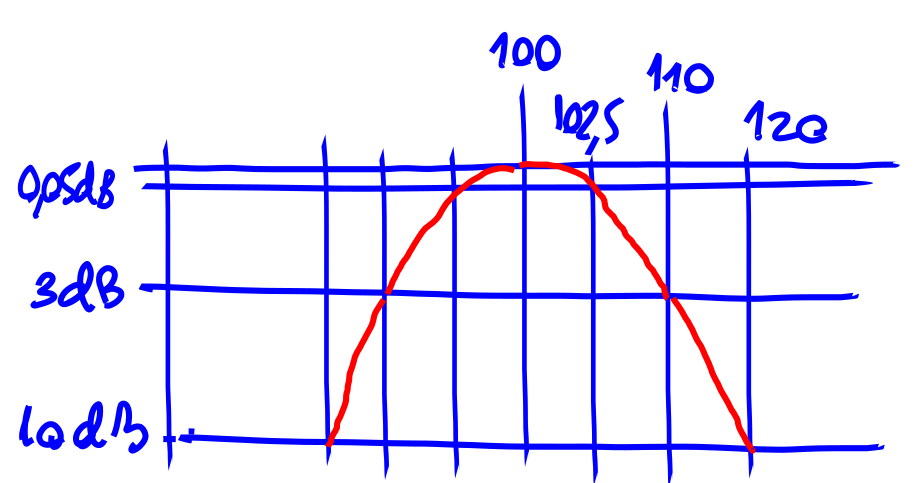

wc=B/2;                             % frecuencia de corte del filtro pasa bajos.
bpToLp=@(w, w0, wc) (w-w0)/(wc);

(c’) La atenuación máxima permitida en la banda de paso de $\omega=0$ a  $\omega=0.25 rad./seg.$ es de $0.05db$

wNp=bpToLp(wp, w0, wc)    %rad/seg

wNp = 0.2500

(d') La atenuación mínima requerida en la banda suprimida es de  $10dB$ para $\omega>=2 rad./sec.$

wNs=bpToLp(ws, w0, wc)    %rad/seg

wNs = 2

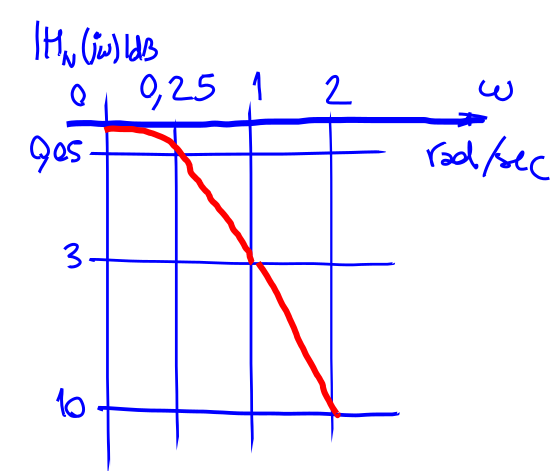

**Cálculo del orden del filtro**

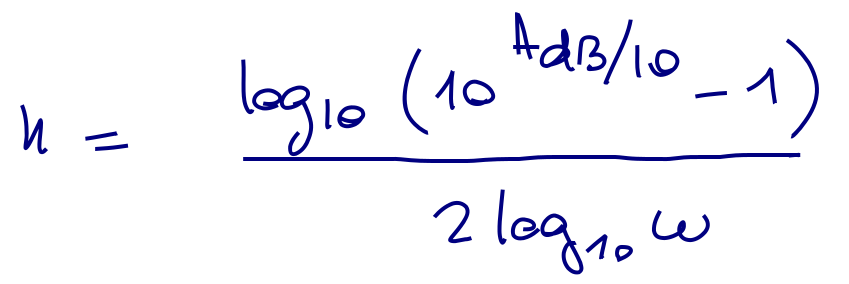

orden = @(w,A) (log10(10^(A/10)-1))/(2*log10(w));

- **Cálculo de n - Según la banda de paso**

n1=orden(wNp, Ap)

n1 = 1.6081

- **cálculo de n - Según la banda de supresión**

n2=orden(wNs, As)

n2 = 1.5850


n=n2;
if n2>n1 
  n=n1;
end
n=ceil(n)

n = 2

**Función de transferencia**

**1- opción por polos**

syms k 'integer';
theta(k)=(2*k-1)/(2*n)*pi;

sk(k)=cos(theta(k))+j*sin(theta(k))

$$sk(k) = \cos\left(1.5708\,k-0.7854\right)+1\,\sin\left(1.5708\,k-0.7854\right)\,\mathrm{i}$$

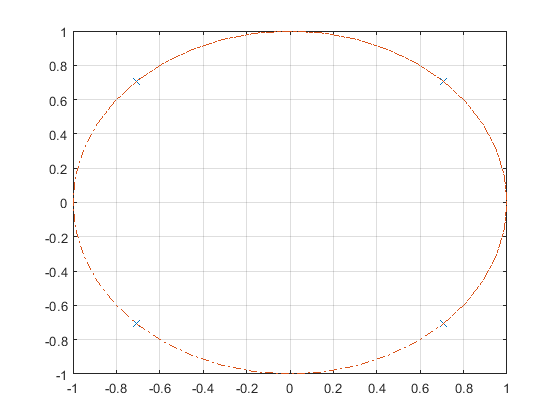


m=0:0.1:2*pi;
plot(real(sk(1:2*n)), imag(sk(1:2*n)),'X'), hold on, ...
plot( sk(m),'-.' ), ...
xlim([-1,1]); ylim([-1,1]); grid on; hold off; 

syms s
D(s)=prod(s-sk(2:3));
D(s)=collect(D(s));
H(s)=1/vpa(D(s),3)

$$H(s) = \frac{1}{s^{2}+1.4142\,s+1}$$

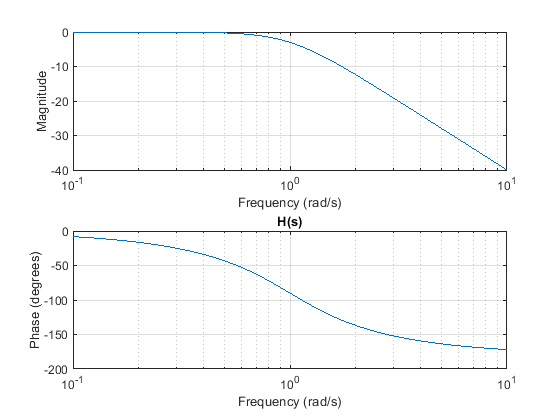

plotdb(H(s), -1, 1); title('H(s)');

**Mapeo de pasa bajos a pasa medios  **

Hbp(s)=collect( H( ( s^2 + w0^2 ) /(B*s) )) 

$$Hbp(s) = \frac{6.7109e+15\,s^{2}}{16777216\,s^{4}+4.7453e+11\,s^{3}+3.4226e+17\,s^{2}+4.7453e+21\,s+1.6777e+27}$$

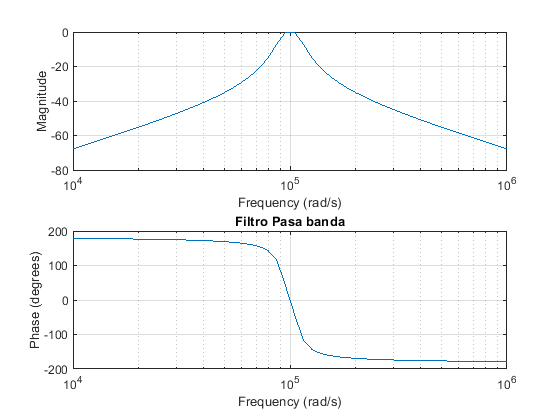

plotdb(Hbp(s), 4,6); title('Filtro Pasa banda');

**Implementación - darlington**

syms K, Rl=1, Rs=1;

Rl = 1


K1=vpasolve(K*Hbp(w0)==Rl/(Rl+Rs),K)

$$K1 = 57.5711$$

H_pa(s)=K1*Hbp(s);
rho2(s) = 1 - 4*Hbp(s)*Hbp(-s);
collect(rho2(s))

$$ans = \frac{2.8147e+14\,s^{8}+1.1259e+25\,s^{6}+1.6875e+35\,s^{4}+1.1259e+45\,s^{2}+2.8147e+54}{2.8147e+14\,s^{8}+1.1259e+25\,s^{6}+1.6893e+35\,s^{4}+1.1259e+45\,s^{2}+2.8147e+54}$$


[B,A]=numden(rho2(s));
a=sym2poly(A);
b=sym2poly(B);
a0=a(1); a=a/a0; b=b/a0;
rz=roots(b)

rz = 	1.0e+05 *

   0.0000 + 1.1405i
   0.0000 - 1.1405i
  -0.1318 + 0.9913i
  -0.1318 - 0.9913i
   0.1318 + 0.9913i
   0.1318 - 0.9913i
   0.0000 + 0.8768i
   0.0000 - 0.8768i



rp=roots(a)

rp = 	1.0e+05 *

  -0.0752 + 1.0703i
  -0.0752 - 1.0703i
   0.0752 + 1.0703i
   0.0752 - 1.0703i
  -0.0653 + 0.9297i
  -0.0653 - 0.9297i
   0.0653 + 0.9297i
   0.0653 - 0.9297i


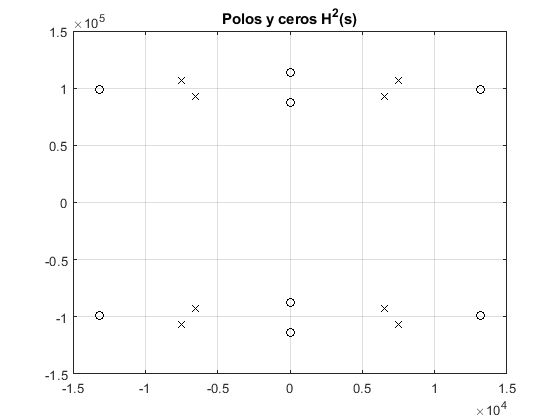


% Trazando los polos para inspeccionar si se cumple la simetria cuadrantal
clf,plot(real(rz), imag(rz), 'ko'), hold on;
plot(real(rp), imag(rp), 'kX'), grid on, hold off;
title('Polos y ceros H^2(s)');

- **Coeficiente de reflexión**

rho(s)=a0*collect(prod(s-LH(rz)))/collect(prod(s-LH(rp)))

$$rho(s) = \frac{2.8147e+14\,s^{2}+7.4190e+18\,s+2.8147e+24}{s^{4}+2.8108e+04\,s^{3}+2.0395e+10\,s^{2}+2.8108e+14\,s+1.0000e+20}$$

- **Impedancia de Entrada - función característica a implementar**

Solución 1

Zin1(s)=Rs*(1-rho(s))/(1+rho(s));
fprintf("Normalizada, Zin1(s)="), MyNormalizador(Zin1(s))

Normalizada, Zin1(s)=

'MyNormalizador' is not found in the current folder or on the MATLAB path, but exists in:
    F:\data\workspaces\workspace-facultad\electronica\electronica_IV\teoria_de_los_circuitos_II\tp\matlab

Change the MATLAB current folder or add its folder to the MATLAB path.

Solución 2

Zin2(s)=Rs*(1+rho(s))/(1-rho(s));
fprintf("Normalizada, Zin1(s)="), MyNormalizador(Zin2(s))

**Implementación - normalizado**

display(cauer( Zin1(s), 1) )

**Implementación - desnormalizado**

display(cauer( Zin2(s), 2) )

**Transformación por Integración numérica - método de euler**

Ts=sym(2*pi/1E7);

syms z, syms T 'real';
HzT(z)=subs(H_pa(s), s=(1-z^-1)/T ) ;

HzT(z)=collect(HzT(z),z^-1 )

- **Evaluando **$H_z(z)$** el periodo de muestreo en **$T=1$**;**

Hz(z)=subs(HzT(z),T=sym(Ts))

- **Respuesta en frecuencia, forma alternativa.**

syms theta 'real'; 
clf; ezplot(20*log(abs(Hz(exp(j*theta)))),[0,pi]), 
title('Magnitud en db'), grid on, 
ylabel('Magnitud (dB)'), 
xlabel('Normalizado en frecuencia (\pi \times rad/muestras)'),

**Comparativa caso analógico - caso digital**

syms w 'real';
clf; ezplot(20*log10(abs( H_pa(w/Ts) )),[0,pi]), hold on,
ezplot(20*log10(abs(Hz(exp(j*theta)))),[0,pi]), hold off; grid on; 
legend('Caso analógico', 'Caso Digital'); title('Comparativa');